clear; clc; 

eps = 0.005;
funcQtd = [2, 3, 2];
alph = 0.008; 

#### Define as funções e os dados de entrada

load('C:\Users\gabri\OneDrive\Área de Trabalho\scholl\AI\7-Neuro-Fuzzy\inflow2.mat');
[lineQtd, colQtd] = size(xt);

funcDef = zeros(length(funcQtd),3);
for i = 1:1:length(funcQtd)
    funcDef(i,1) = funcQtd(i);
end

funcQtdS = sum(funcQtd);


funcs = [];
for i = 1:1:colQtd
    funcDef(i,2) = min(xt(:,i));
    funcDef(i,3) = max(xt(:,i));
    funcs = [funcs triComp(funcDef(i,:))];
end

#### Plota as funções de transferências definidas

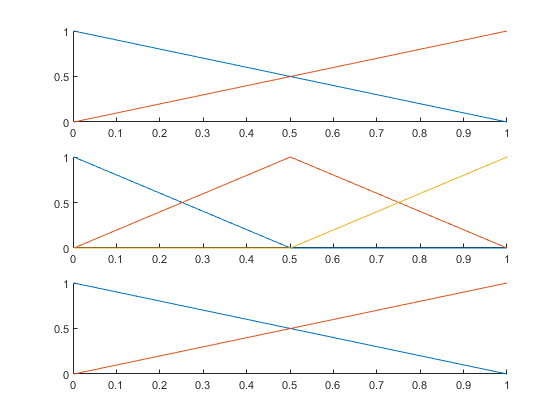

cont=0; clf; figure(1);
for i = 1:1:colQtd
    subplot(colQtd,1,i); hold on;
    for j =1:1:funcDef(i,1)
        cont = cont + 1;
        fplot(@(x)funcs{cont}(x), [funcDef(i,2), funcDef(i,3)]); 
    end
    hold off; 
end

#### Define os pesos iniciais de cada neurônio

w = linspace(0.3,0.5,funcQtdS);

#### Passa os dados de entrada pela rede (Treinamento)

outs = linspace(1,1,colQtd); 
pertinence = linspace(1,1,funcQtdS); errFun = [];

for i = 1:1:lineQtd               % Caminha por todo conjunto de dados       
    cont = 1; 
    for j = 1:1:colQtd            % Passa por todas as entradas da amostra
        start = cont;  
        for k = 1:1:funcDef(j,1)  % Verifica a entrada em cada função
            pertinence(cont) = funcs{cont}(xt(i,j));
            cont = cont+1;
        end
        outs(j) = neuron(pertinence(start:cont-1), w(start:cont-1));
    end
    err = yt(i) - sum(outs);
    errFun = [errFun err];
    if abs(err) > eps
       % alph = 1 / sum(pertinence.^2);
       for j = 1:1:length(w)
           w(j) = w(j) + alph*pertinence(j)*err;
       end
    end
end

#### Executa o modelo nos dados de entrada (Teste)

outs = linspace(1,1,colQtd); result = linspace(1,1,lineQtd);
pertinence = linspace(1,1,funcQtdS); 

for i = 1:1:lineQtd               % Caminha por todo conjunto de dados       
    cont = 1; 
    for j = 1:1:colQtd            % Passa por todas as entradas da amostra
        start = cont;  
        for k = 1:1:funcDef(j,1)  % Verifica a entrada em cada função
            pertinence(cont) = funcs{cont}(xt(i,j));
            cont = cont+1;
        end
        outs(j) = neuron(pertinence(start:cont-1), w(start:cont-1));
    end
    result(i) = sum(outs);
end

#### Plota os resultados obtidos com os esperados

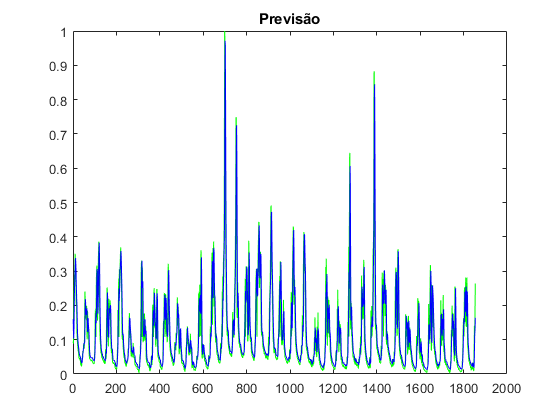

x = 1:1:length(yt);
clf; figure(2); 
plot(x, yt', '-g', x, result, '-b'); title("Previsão")

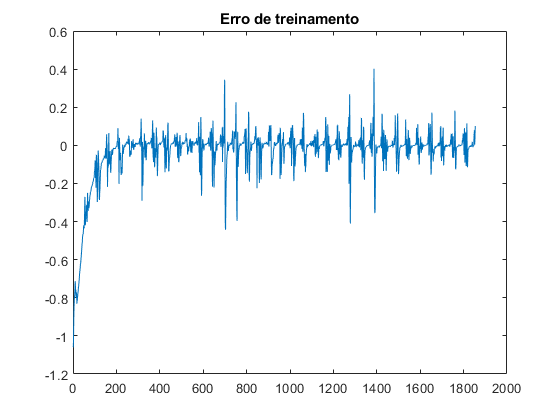

figure(3); 
plot(x, errFun); title("Erro de treinamento")

var(yt' - result)   % Variancia da previsão

ans = 0.0034

Pelo plot do erro, é possivel observar a acertividade do modelo gerando uma baixa variância.

#### Functions

Triângulo complementar (função de pertinência das entradas)

function res = triComp(funcDefPos)
    res = cell(1, funcDefPos(1));
    center = funcDefPos(2);
    space = (funcDefPos(3) - funcDefPos(2)) / (funcDefPos(1)-1);
    for i=1:1:funcDefPos(1)
        res(i) = {@(x)triangle(x,center-space, center, center+space)};
        center = center + space;
    end
end

Definição da função triangular

function res = triangle(x,a,m,b)
    res = max(min((x-a)/(m-a), (b-x)/(b-m)), 0);
end

Define um neurônio e sua determinada saída

function res = neuron(per, w)
    res = sum(per.*w);
end